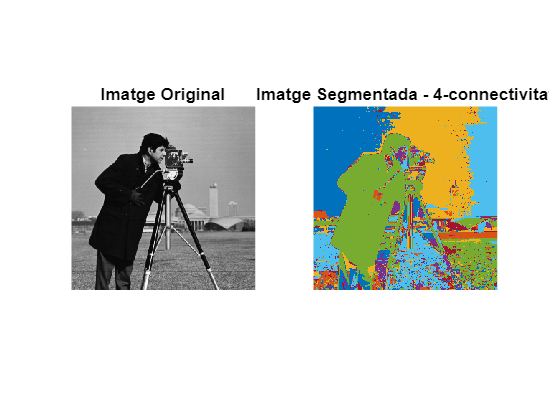

% PRACTICA 2: Segmentació d’imatges en grisos mitjançant creixement de regió

% Iniciem un comptador de temps per saber quant triga tot el procés de segmentació
tic 

% Llegim la imatge
imatge = imread('cameraman.tif');

% Comprovem si la imatge és en color (RGB) i la convertim a escala de grisos si cal
if size(imatge, 3) == 3
    imatge = rgb2gray(imatge);
end

% Convertim la imatge a tipus double per poder fer operacions amb decimals.
% Això NO normalitza els valors a [0,1], simplement ens permet calcular mitjanes amb decimals.
matriu = double(imatge);

% Inicialitzem la matriu resultat amb zeros (mateixa mida que la imatge)
Resultat = zeros(size(matriu));

% Primera etiqueta per a la primera regió trobada
etiqueta = 1;

% Llindar de similitud per considerar si un píxel pertany a la regió
th = 15;

% Definim el tipus de connectivitat: 4 o 8 (es pot modificar lliurement aquí)
Conectivitat = 4;  % ← Canvia-ho a 4 o 8 segons es desitgi

% Utilitzem una cua estàtica (prealocada) per evitar el cost de redimensionar arrays en temps d'execució, guanyant eficiència en memòria i velocitat
mida_cua = size(matriu,1) * size(matriu,2);
vector_x = zeros(mida_cua, 1);  % Coordenades X dels píxels a explorar
vector_y = zeros(mida_cua, 1);  % Coordenades Y dels píxels a explorar

% Busquem el primer píxel no etiquetat
[x, y] = find(Resultat == 0, 1);

% Bucle principal: mentre quedin píxels sense etiquetar
while (~isempty(x))
    mitjana = matriu(x, y);
    comptador = 1;
    Resultat(x, y) = etiqueta;

    % Inicialitzem la cua amb aquest primer píxel
    inici = 1;
    final = 1;
    vector_x(final) = x;
    vector_y(final) = y;

    % Definim els offsets segons la connectivitat triada
    if Conectivitat == 4
        % Veïnatge 4-connectat
        offsets = [ -1,  0;   % Esquerra
                     0,  1;   % Dalt
                     1,  0;   % Dreta
                     0, -1];  % Baix
    elseif Conectivitat == 8
        % Veïnatge 8-connectat
        offsets = [ -1,  0;    % Esquerra
                   -1,  1;    % Diagonal superior esquerra
                    0,  1;    % Dalt
                    1,  1;    % Diagonal superior dreta
                    1,  0;    % Dreta
                    1, -1;    % Diagonal inferior dreta
                    0, -1;    % Baix
                   -1, -1];   % Diagonal inferior esquerra
    else
        error('El valor de Conectivitat ha de ser 4 o 8.');
    end

    % Inici del creixement de la regió
    while (inici <= final)
        % 'inici' apunta al pròxim píxel de la cua a processar
        % 'final' és on afegim nous píxels a la cua
        x1 = vector_x(inici);
        y1 = vector_y(inici);
        inici = inici + 1;

        for i = 1:size(offsets, 1)
            pixel_x = x1 + offsets(i, 1);
            pixel_y = y1 + offsets(i, 2);

            % Comprovem límits de la imatge
            if (pixel_x > 0 && pixel_x <= size(matriu,1) && pixel_y > 0 && pixel_y <= size(matriu,2))
                % Si el píxel encara no està etiquetat
                if (Resultat(pixel_x, pixel_y) == 0)
                    % Si la intensitat del veí és prou similar a la mitjana
                    if abs(matriu(pixel_x, pixel_y) - mitjana) <= th
                        % Etiquetem el píxel i l’afegim a la cua
                        Resultat(pixel_x, pixel_y) = etiqueta;
                        final = final + 1;
                        vector_x(final) = pixel_x;
                        vector_y(final) = pixel_y;

                        % Actualitzem la mitjana de la regió
                        comptador = comptador + 1;
                        mitjana = (mitjana * (comptador - 1) + matriu(pixel_x, pixel_y)) / comptador;
                    end
                end
            end
        end
    end

    % Busquem un nou píxel no etiquetat per començar una nova regió
    [x, y] = find(Resultat == 0, 1);
    etiqueta = etiqueta + 1;
end

% Convertim les etiquetes en colors aleatoris per visualitzar les regions
matriu_final = label2rgb(Resultat, lines(max(Resultat(:))), 'b', 'shuffle');

% Mostrem les imatges
figure;
subplot(1, 2, 1), imshow(imatge), title('Imatge Original');
subplot(1, 2, 2), imshow(matriu_final), title(['Imatge Segmentada - ', num2str(Conectivitat), '-connectivitat']);


% Mostrem el temps de còmput total
toc

Elapsed time is 0.742487 seconds.
